clear;
clc;
% Generate training data
trueModel = @(t,y) [1;12*(y(1)-0.5)^2+10*(4*(y(1)-0.5)^3+0.5-y(2))];
numTimeSteps = 101;
T = 1;
t = linspace(0, T, numTimeSteps);
[~, xTrain] = ode45(trueModel, t, [0; 0]);
x = xTrain(:,1);
y = xTrain(:,2);
Xt = tonndata(x,false,false);
Tt = tonndata(y,false,false);
% Solve an Autoregression Problem with External Input with a NARX Neural Network
% Script generated by Neural Time Series app
% Created 13-Aug-2025 10:02:44
%
% This script assumes these variables are defined:
%
%   x - input time series.
%   y - feedback time series.

% % X = tonndata(x,false,false); % 1×101 cell
% % T = tonndata(y,false,false); % 1×101 cell
idx = {1:37, 33:69, 65:101};
xList = cellfun(@(r) tonndata(xTrain(r,1), false, false), idx, 'UniformOutput', false);
yList = cellfun(@(r) tonndata(xTrain(r,2), false, false), idx, 'UniformOutput', false);

[x1, x2, x3] = xList{:};
[y1, y2, y3] = yList{:};

X = catsamples(x1,x2,x3,'pad');
T = catsamples(y1,y2,y3,'pad');

% Choose a Training Function
% For a list of all training functions type: help nntrain
% 'trainlm' is usually fastest.
% 'trainbr' takes longer but may be better for challenging problems.
% 'trainscg' uses less memory. Suitable in low memory situations.
trainFcn = 'trainbr';  % Levenberg-Marquardt backpropagation.

% Create a Nonlinear Autoregressive Network with External Input
inputDelays = 1:1;
feedbackDelays = 1:1;
hiddenLayerSize = 10;
net = narxnet(inputDelays,feedbackDelays,hiddenLayerSize,'open',trainFcn);

% Choose Input and Feedback Pre/Post-Processing Functions
% Settings for feedback input are automatically applied to feedback output
% For a list of all processing functions type: help nnprocess
% Customize input parameters at: net.inputs{i}.processParam
% Customize output parameters at: net.outputs{i}.processParam
net.inputs{1}.processFcns = {'removeconstantrows','mapminmax'};
net.inputs{2}.processFcns = {'removeconstantrows','mapminmax'};

% Prepare the Data for Training and Simulation
% The function PREPARETS prepares timeseries data for a particular network,
% shifting time by the minimum amount to fill input states and layer
% states. Using PREPARETS allows you to keep your original time series data
% unchanged, while easily customizing it for networks with differing
% numbers of delays, with open loop or closed loop feedback modes.
[x,xi,ai,t] = preparets(net,X,{},T);

% Setup Division of Data for Training, Validation, Testing
% For a list of all data division functions type: help nndivision
net.divideFcn = 'dividerand';  % Divide data randomly
net.divideMode = 'time';  % Divide up every sample
net.divideParam.trainRatio = 70/100;
net.divideParam.valRatio = 15/100;
net.divideParam.testRatio = 15/100;

% Choose a Performance Function
% For a list of all performance functions type: help nnperformance
net.performFcn = 'mse';  % 均方误差

% Choose Plot Functions
% For a list of all plot functions type: help nnplot
net.plotFcns = {'plotperform','plottrainstate', 'ploterrhist', ...
    'plotregression', 'plotresponse', 'ploterrcorr', 'plotinerrcorr'};

% Train the Network
[net,tr] = train(net,x,t,xi,ai);

% Test the Network
y = net(x,xi,ai);
e = gsubtract(t,y);
performance = perform(net,t,y)

performance = 2.9673e-10


% Recalculate Training, Validation and Test Performance
trainTargets = gmultiply(t,tr.trainMask);
valTargets = gmultiply(t,tr.valMask);
testTargets = gmultiply(t,tr.testMask);
trainPerformance = perform(net,trainTargets,y)

trainPerformance = 2.8688e-10

valPerformance = perform(net,valTargets,y)

valPerformance = NaN

testPerformance = perform(net,testTargets,y)

testPerformance = 3.5782e-10


% Closed Loop Network
% Use this network to do multi-step prediction.
% The function CLOSELOOP replaces the feedback input with a direct
% connection from the output layer.
netc = closeloop(net);
netc.name = [net.name ' - Closed Loop'];
[xc,xic,aic,tc] = preparets(netc,X,{},T);
netc = train(netc, xc, tc, xic, aic);
yc = netc(xc,xic,aic);
closedLoopPerformance = perform(net,tc,yc)

closedLoopPerformance = 9.0436e-10

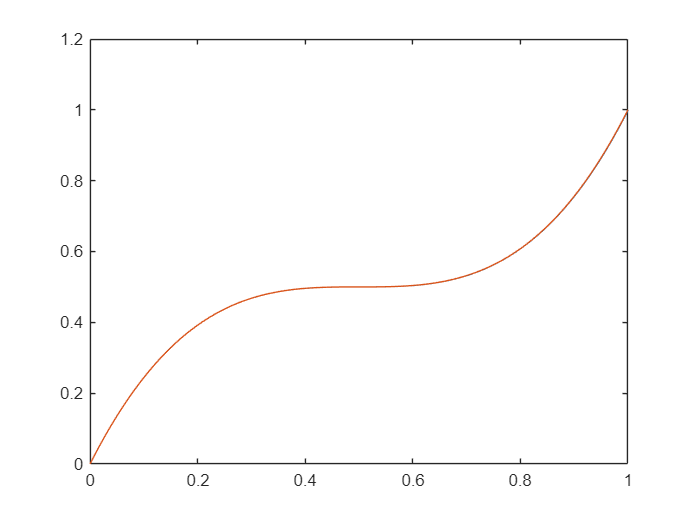


% Multi-step Prediction
% Sometimes it is useful to simulate a network in open-loop form for as
% long as there is known output data, and then switch to closed-loop form
% to perform multistep prediction while providing only the external input.
% Here all but 5 timesteps of the input series and target series are used
% to simulate the network in open-loop form, taking advantage of the higher
% accuracy that providing the target series produces:

numTimesteps = 101;
knownOutputTimesteps = 1:1;  
predictOutputTimesteps = 2:numTimesteps;
X1 = Xt(knownOutputTimesteps);
T1 = Tt(knownOutputTimesteps);
[x1,xio,aio] = preparets(net,X1,{},T1);
[y1,xfo,afo] = net(x1,xio,aio);
% Next the the network and its final states will be converted to
% closed-loop form to make five predictions with only the five inputs
% provided.
x2 = Xt(:,predictOutputTimesteps);
[netc,xic,aic] = closeloop(net,xfo,afo);
[y2,xfc,afc] = netc(x2,xic,aic);
multiStepPerformance = perform(net,Tt(1,predictOutputTimesteps),y2);
plot(cell2mat(x2),cell2mat(y2),xTrain(:,1),xTrain(:,2));